# Fuzzy Clustering

ECPE 226 

Stephanie Torres

clearvars
load('clusterdata.mat');  

whos

cluster_data = clusterdemo;

% parameters
C = 3; % 3 clusters
m = 2; % fuzziness component 
epsilon = 1e-3; % convergence 
max_iter = 100;

initial_centers = cluster_data(randperm(size(cluster_data, 1), C), :); % random initialization of cluster centers 

% initializing (membership matrix, cluster centers, obj function)
U = initMembership(cluster_data, C);
V = findClusterCenters(U, cluster_data, m);
last_obj_fcn = Inf;

% FCM algorithm
for iter = 1:max_iter
    % updating membership values
    U = updateMemberships(cluster_data, V, m);
    V = findClusterCenters(U, cluster_data, m); % calculating cluster centers
    
    % calculating objective function to check for convergence
    obj_fcn = calculateObjectiveFunction(U, cluster_data, V, m);
    
    % checking for convergence
    if abs(last_obj_fcn - obj_fcn) < epsilon
        break;
    end
    
    last_obj_fcn = obj_fcn;
end

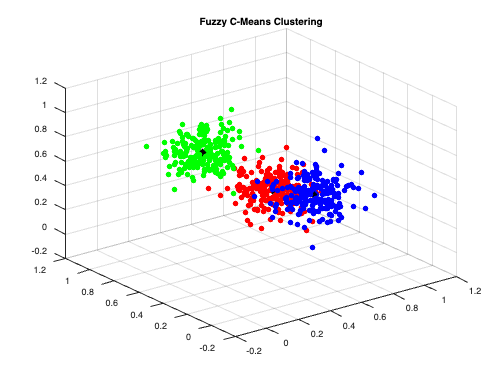

% plotting the results
% assigning each data point to a cluster based on the highest membership value
[~, membership] = max(U, [], 2);

% scatter plot for the clustered data
figure;
hold on;
rgb_colors = [
    1, 0, 0;
    0, 1, 0;
    0, 0, 1;];

for i = 1:C
    % extracting data points for cluster i based on maximum membership value
    cluster_i = cluster_data(membership == i, :);
    scatter3(cluster_i(:, 1), cluster_i(:, 2), cluster_i(:, 3), [], rgb_colors(i, :), 'filled');  
end
scatter3(V(:, 1), V(:, 2), V(:, 3),'kx', 'LineWidth', 6); 
hold off;
title('Fuzzy C-Means Clustering');
grid on;
view(3);

Results:

The objective of this assignment was to partition a dataset into groups with some degree of overlapping membership using the FCM algorithm. The dataset clusterdata.mat was processed through a FCM clustering algorithm. It iteratively updates membership levels and recalculates cluster centers until the change in the objective function in minimal. Parameters that were used: Number of clusters C = 3, Fuzziness index(m) = 2, convergence(epsilon) = 1e-4, max iter =100. The scatter plot here displays the clustering outcome with each point colored according to the cluster with which it has the highest membership. There are three clusters distinguished by colors: first cluster, shown in red, is centered. Second cluster, shown in blue, occupies space to the right quadrant, and lastly the third cluster, represented in green is found in the upper left quadrant. When updating the convergence criterion you may see a shift in the clusters of location. Black crosses mark the centers of each cluster, serving as the point of strongest membership within the respective groups. Ultimately, the FCM clustering worked well applied to the dataset that you provided professor. The visualization of the three clusters, you can see each data point holding varying degrees of association to each cluster. This outcome demonstrates the capability of the FCM algorithm to classify data into clusters where each data point can belong to more than one cluster with varying levels of membership. 

function U = initMembership(cluster_data, C)
    % initializing the fuzzy membership matrix
    U = rand(size(cluster_data, 1), C);
    U = U ./ sum(U, 2);  % normalizing each row to sum to 1
end

function V = findClusterCenters(U, cluster_data, m)
    % calculating the cluster centers
    um = U.^m;
    V = (um' * cluster_data) ./ sum(um', 2);
end

function U = updateMemberships(cluster_data, V, m)
    % updating the membership values for each data point and each cluster
    numData = size(cluster_data, 1);
    C = size(V, 1);
    U = zeros(numData, C);
    
    for i = 1:numData
        for j = 1:C
            sum_u = 0;
            for k = 1:C
                % euclidean distance calculated
                dist_ij = norm(cluster_data(i, :) - V(j, :));  
                dist_ik = norm(cluster_data(i, :) - V(k, :)); 
                sum_u = sum_u + (dist_ij / dist_ik)^(2 / (m - 1));
            end
            U(i, j) = 1 / sum_u;
        end
    end
end

function obj_fcn = calculateObjectiveFunction(U, cluster_data, V, m)
    % calculating the objective function(optimization progress)
    um = U.^m;
    obj_fcn = 0;
    for i = 1:size(V, 1)
        for j = 1:size(cluster_data, 1)
            obj_fcn = obj_fcn + (um(j, i) * norm(cluster_data(j, :) - V(i, :))^2);
        end
    end
end